# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# % Authors: Khanh Dao Duc, Jalal Khouhak

# %         Department of Mathematics 

# %         The University of British Columbia (UBC)

# % 2022

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Script for Fitting Experimental Data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

format shortG

%%%%%%%%% Experimental Data %%%%%%%%%
% Parameter selection input
param_selection = [true; %\ alpha_P - production rate of protein
    false; % alpha_M - production cost of mRNA
    true; % alpha_E - production cost of resources
    true; % delta_P - degradation rate of protein
    false; % delta_M - degradation rate of mRNA
    true; % delta_E - degradation rate of resources
    true; % r_P - recycle of protein into resource
    false; % r_M - recycle of mRNA into resource
    ];
scale_limits = [4 4; 
    -3 -2;
    -3 -2;
    -6 -5;
    -6 -3;
    -6 -3;
    -12 -10;
    -4 -3]; % scale limits for the active parameters in order of appearance/ to initiate the values, we first look at the best order of magnitude to work on with each parameters

% Data input - input your data here
time_points = [5,10,15,20,30,45,60];

file_name = "Rabbit";

% No pre-incubation data
% % 
data_points_no_inc = [134814.2,535553.5,1117699.167,2765650,4676896.667,5991675;
    985829.5,3611828.333,5887583.333,11820630,17519766.67,18695350;
    2096233.333,6740431.667,10085211.67,16204400,20418983.33,22835683.33;
    2372001.66,7418885,10977265,1.70E+07,2.34E+07,2.64E+07;
    2586933.333,8796735,11737600,15891683.33,21423866.67,21460700;
    2641990,7746235,10666288.33,14212783.33,18956433.33,20052250;
    2803356.667,8146876.667,10604476.67,1.60E+07,1.76E+07,1.41E+07];

protein_level_no_inc = transpose(data_points_no_inc(:,[1 2 3 4]));
concentrations_no_inc = [10 25 50 100];


% % Pre-incubation data
data_points_inc = [195026.8333,1930060,128436.5,1866635,100820.2833,1788838.333;
    1038039.167,7076921.667,674758.8333,5255980,502054.1667,4151856.667;
    1648073.333,8311923.333,964648.1667,6081458.333,839117.5,5086518.333;
    1953148.333,9172461.667,1170175.333,6040480,1042688,5222341.667;
    2027258.333,8611016.667,1418876.667,6075821.667,1382448.333,5697188.333;
    2154196.667,7409325,1539318.333,5770991.667,1618433.333,5651486.667;
    2106806.667,6635273.333,1543413.333,5019161.667,1616306.667,5102551.667;];

protein_level_inc = transpose(data_points_inc);
concentrations_inc = [10 50 10 50];
preincubation_times_inc = [15 15 30 30];

choose_inc = [1 2 3 4];
protein_level_inc = protein_level_inc(choose_inc,:);
concentrations_inc = concentrations_inc(choose_inc);
preincubation_times_inc = preincubation_times_inc(choose_inc);

loss_scale = time_points .^-1;
loss_scale = length(loss_scale)*loss_scale/sum(loss_scale);

%%%%%%%%% Auxiliary setup %%%%%%%%% 
% These routines are setup for model fitting - don't change unless necessary
% General Input
n = sum(param_selection); % number of active parameters
preincubation_times_no_inc = zeros(1, length(concentrations_no_inc));
protein_level = [protein_level_no_inc; protein_level_inc];
concentrations = [concentrations_no_inc concentrations_inc];
preincubation_times = [preincubation_times_no_inc preincubation_times_inc];
param_selection = transpose(param_selection);

% Nelder-Mead Parameters
Nb_step = 2000;
neld_param = [1 0.5 2 0.5];

% Simulation Parameters (Runge Kutta)
TIME = ceil(max(time_points)/10)*10;  % Time of simulation (in min)
deltat = 0.1; % Numerical time step (min)

Starting IVT model fit with following parameters turned on:
    "a_P"    "a_R"    "d_P"    "d_R"    "betta"

Scale found:
        10000        0.001        0.001        1e-05        0.001

Starting Nelder-Mead method with 2000 steps. 
Progress: 10% (step 200) 
   3.0588e+05     0.016957   2.3056e-05   0.00014831     0.012261

Progress: 20% (step 400) 
        89274    0.0026275   3.2206e-05   0.00038986     0.049104

Progress: 30% (step 600) 
        68775    0.0019896   4.0152e-05    0.0003312     0.063871

Progress: 40% (step 800) 
        36794    0.0010846    3.814e-05   0.00026906      0.14802

Progress: 50% (step 1000) 
        36049    0.0010688   3.7872e-05   0.00026515      0.15248

Progress: 60% (step 1200) 
        36049    0.0010688   3.7872e-05   0.00026515      0.15248

Progress: 70% (step 1400) 
        36049    0.0010688   3.7872e-05   0.00026515      0.15248

Progress: 80% (step 1600) 
        36049    0.0010688   3.7872e-05   0.00026515      0.15248

Progress: 90% (st

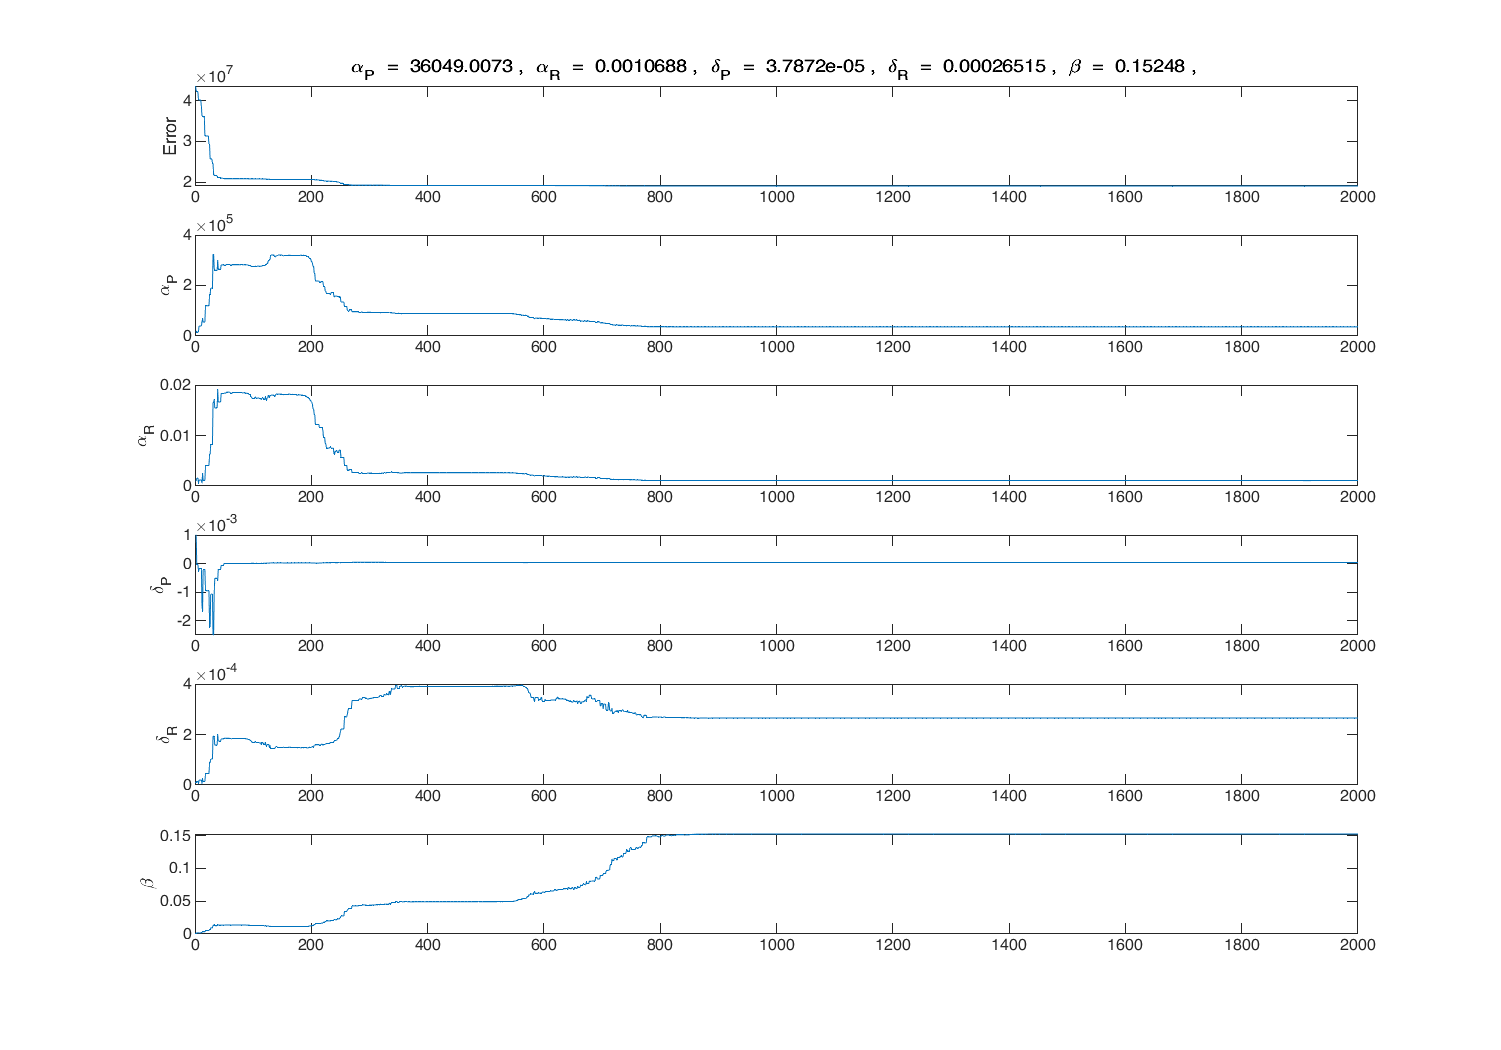

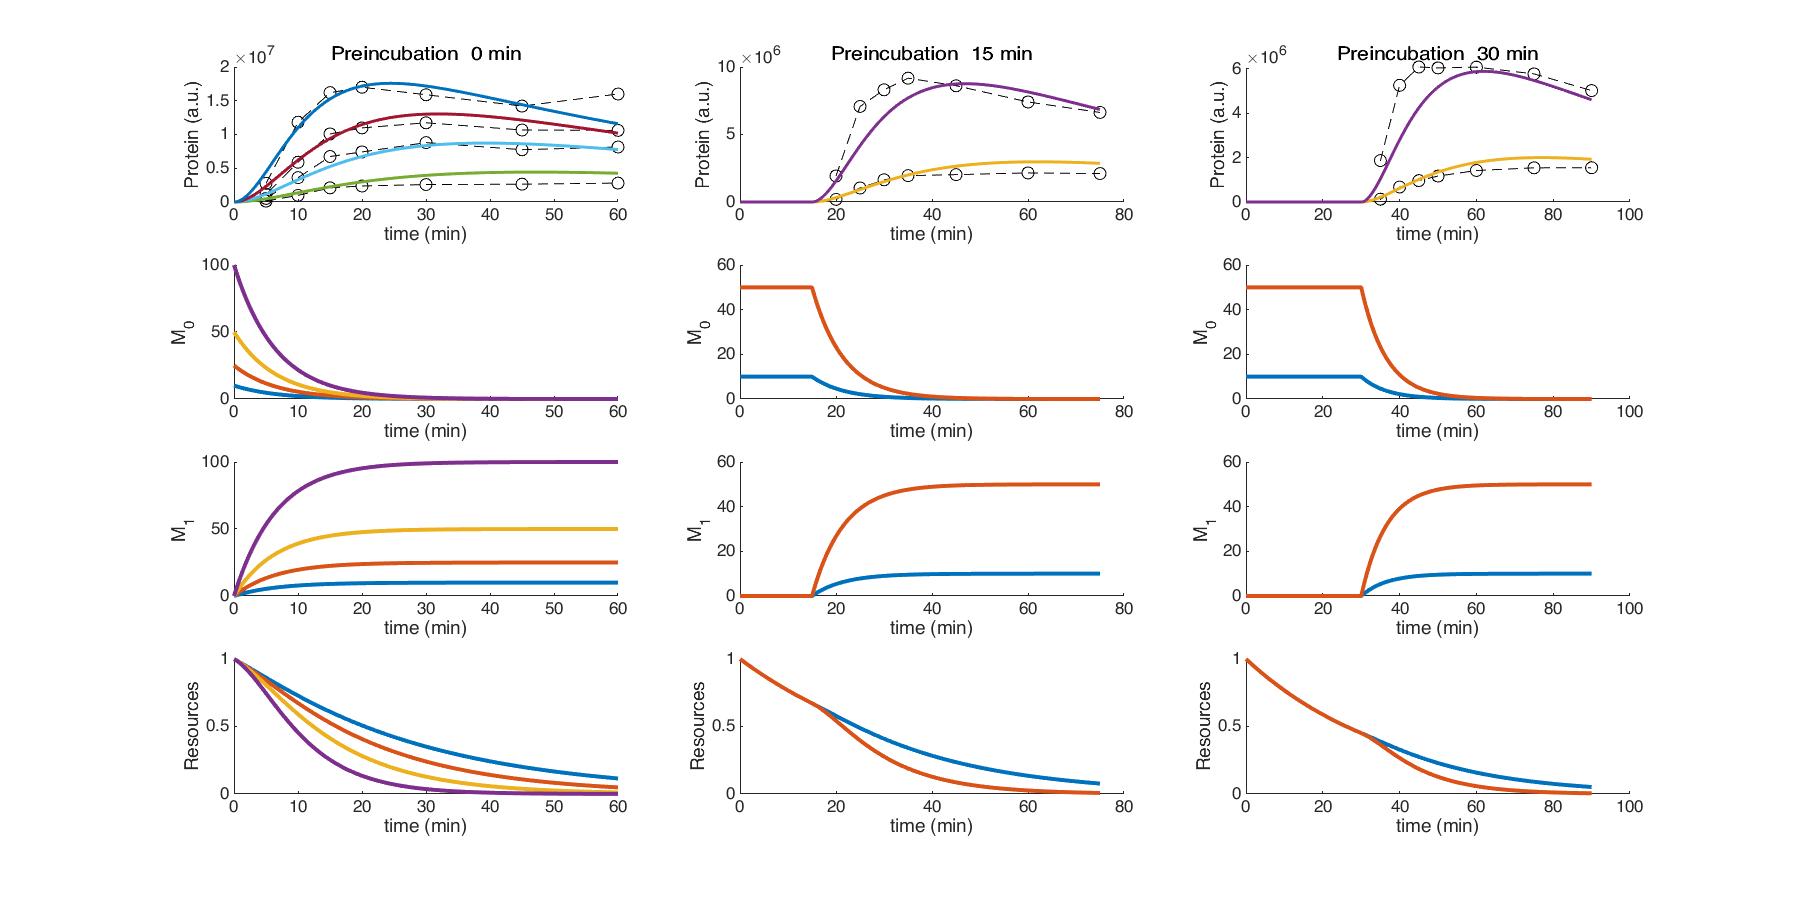

Final Parameter Values:
    "a_P"    "a_R"    "d_P"    "d_R"    "betta"

        36049    0.0010688   3.7872e-05   0.00026515      0.15248

Final Error:
    1.902e+07



%%%%%%%%% Model Fit %%%%%%%%%
params = IVT_model_fit_complete(scale_limits, ...
    time_points, ...
    protein_level, ...
    concentrations, ...
    preincubation_times, ...
    n, param_selection, ...
    Nb_step, neld_param, TIME, deltat, ...
    file_name, loss_scale);

%%%%%%%%% Model Plotting %%%%%%%%%
% close;
% param_setting = [1e4 1e-3 1e-3 1e-3 1e-5 1e-3];
% disp(param_setting);
% IVT_model_fit_plot(scale_limits, time_points, protein_level, concentrations, ...
%   preincubation_times, n, param_selection, TIME, deltat, param_setting)
%%%%%%%%%%%%%%% Steady State %%%%%%%%%
%alpha_p = params(1);
% alpha_m = params(2);
% alpha_e = params(3);
% delta_p = params(4);
% delta_m = params(5);
% delta_e = params(6);
% r_p = params(7);
% betta = (r_p/delta_e - (alpha_e*delta_p)/(delta_e*alpha_p)*(-alpha_m*delta_p/(delta_m*alpha_p)));
% P_ss = delta_p/(betta*alpha_p);
% M_ss = (-alpha_m/(betta*delta_m))*(delta_p/alpha_p)^2;
% R_ss = ((r_p*delta_p/(betta*delta_e*alpha_p)) - (alpha_e/(betta*delta_e))*(delta_p/alpha_p)^2);